clear
clc

num = [15 3]

num =     15     3


den = [90 10 1]

den =     90    10     1


G = tf(num, den)

G =
 
      15 s + 3
  -----------------
  90 s^2 + 10 s + 1
 
Continuous-time transfer function.



T_d = 5;
G_d = c2d(G,T_d,'zoh')

G_d =
 
     0.9518 z - 0.327
  ----------------------
  z^2 - 1.365 z + 0.5738
 
Sample time: 5 seconds
Discrete-time transfer function.



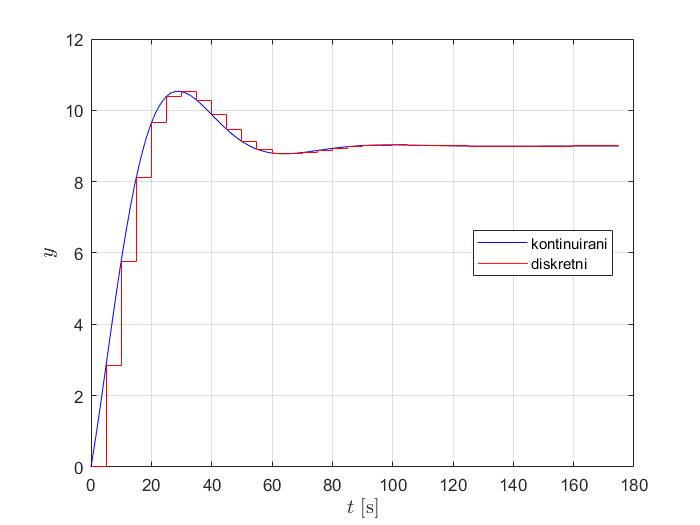


[num_d,den_d] = tfdata(G_d,'v');

% početni uvjeti
y_p1 = 0;
y_p2 = 0;
y_p3 = 0;
u_p1 = 0;
u_p2 = 0;

% broj točaka i priprema vektora za crtanje rezultata
N = 36;
y_d = zeros(N,1);
t_d = zeros(N,1);
u = 3;

for i = 1:N
    % rekurzivna relacija:
    y = -den_d(2)*y_p1 - den_d(3)*y_p2 + num_d(2)*u_p1 + num_d(3)*u_p2;
    % osvjezavanje vrijednosti u proslim koracima
    y_p2 = y_p1;
    y_p1 = y;
    u_p2 = u_p1;
    u_p1 = u;
    % punjenje vektora za crtanje rezultata
    y_d(i) = y;
    t_d(i) = (i-1)*T_d;
end

[y_k,t_k] = step(G,(N-1)*T_d);
plot(t_k,y_k*u,'b')
grid on
hold on
stairs(t_d,y_d,'r')
hold off
xlabel('$t$ [s]','interpreter','latex','fontsize',12)
ylabel('$y$','interpreter','latex','fontsize',12)
legend('kontinuirani','diskretni','location','best')